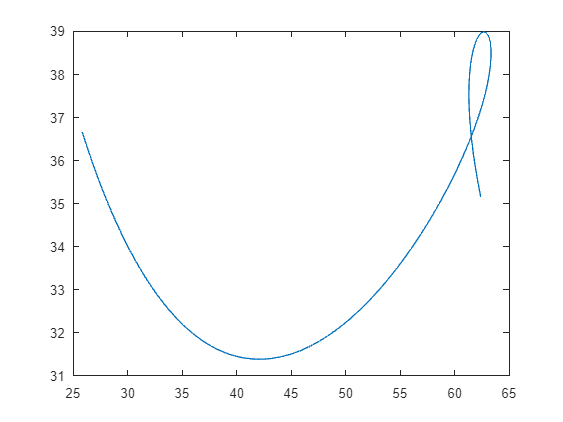

%24/02/2024 WORKING K=4 B-SPLINE ALGORITHM WITH UNIFORM KNOT VECTOR
SumNPx = 0;
SumNPy = 0;
k1 = [];
k2 = [];
k3 = [];
Stackx = [];
Stacky = [];
%for k = 4
P1 = [0,100];
P2 = [20,20];
P3 = [75,40];
P4 = [50,40];
P5 = [100,10];
%Uniform
t1 = 0;
t2 = 10;
t3 = 20;
t4 = 30;
t5 = 40;
t6 = 50;
t7 = 60;
t8 = 70;
t9 = 80;
tmin = t4;
tmax = t6;
step = 0.1;
Knot = [t1,t2,t3,t4,t5,t6,t7,t8,t9];
for t = tmin:step:tmax-step
    if (t1<=t)
        if (t<t2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (t2<=t)
        if (t<t3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (t3<=t)
        if (t<t4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (t4<=t)
        if (t<t5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (t5<=t)
        if (t<t6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (t6<=t)
        if (t<t7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end
    if (t7<=t)
        if (t<t8)
            N7k1 = 1;
        else
            N7k1 = 0;
        end
    else
        N7k1 = 0;
    end
    if (t8<=t)
        if (t<t9)
            N8k1 = 1;
        else
            N8k1 = 0;
        end
    else
        N8k1 = 0;
    end
    N1k2 = ((t-t1)/(t2-t1))*N1k1 + ((t3-t)/(t3-t2))*N2k1;
    N2k2 = ((t-t2)/(t3-t2))*N2k1 + ((t4-t)/(t4-t3))*N3k1;
    N3k2 = ((t-t3)/(t4-t3))*N3k1 + ((t5-t)/(t5-t4))*N4k1;
    N4k2 = ((t-t4)/(t5-t4))*N4k1 + ((t6-t)/(t6-t5))*N5k1;
    N5k2 = ((t-t5)/(t6-t5))*N5k1 + ((t7-t)/(t7-t6))*N6k1;
    N6k2 = ((t-t6)/(t7-t6))*N6k1 + ((t8-t)/(t8-t7))*N7k1;
    N7k2 = ((t-t7)/(t8-t7))*N7k1 + ((t9-t)/(t9-t8))*N8k1;

    N1k3 = ((t-t1)/(t3-t1))*N1k2 + ((t4-t)/(t4-t2))*N2k2;
    N2k3 = ((t-t2)/(t4-t2))*N2k2 + ((t5-t)/(t5-t3))*N3k2;
    N3k3 = ((t-t3)/(t5-t3))*N3k2 + ((t6-t)/(t6-t4))*N4k2;
    N4k3 = ((t-t4)/(t6-t4))*N4k2 + ((t7-t)/(t7-t5))*N5k2;
    N5k3 = ((t-t5)/(t7-t5))*N5k2 + ((t8-t)/(t8-t6))*N6k2;
    N6k3 = ((t-t6)/(t8-t6))*N6k2 + ((t9-t)/(t9-t7))*N7k2;

    N1k4 = ((t-t1)/(t4-t1))*N1k3 + ((t5-t)/(t5-t2))*N2k3;
    N2k4 = ((t-t2)/(t5-t2))*N2k3 + ((t6-t)/(t6-t3))*N3k3;
    N3k4 = ((t-t3)/(t6-t3))*N3k3 + ((t7-t)/(t7-t4))*N4k3;
    N4k4 = ((t-t4)/(t7-t4))*N4k3 + ((t8-t)/(t8-t5))*N5k3;
    N5k4 = ((t-t5)/(t8-t5))*N5k3 + ((t9-t)/(t9-t6))*N6k3;
    SumNPx = N1k4*P1(1,1) + N2k4*P2(1,1) + N3k4*P3(1,1) + N4k4*P4(1,1) + N5k4*P5(1,1);
    SumNPy = N1k4*P1(1,2) + N2k4*P2(1,2) + N3k4*P3(1,2) + N4k4*P4(1,2) + N5k4*P5(1,2);
    Stackx = [Stackx; SumNPx];
    Stacky = [Stacky; SumNPy];
    %k1 = [k1; N1k1, N2k1, N3k1, N4k1, N5k1, N6k1, N7k1];
    %k2 = [k2; N1k2, N2k2, N3k2, N4k2, N5k2, N6k2];
    %k3 = [k3; N1k3, N2k3, N3k3, N4k3, N5k3];
end
%k1
%k2
%k3
%CleanX = nonzeros(Stackx);
%CleanY = nonzeros(Stacky);
%StackPlot = [Stackx, Stacky]
%Stackx(isnan(Stackx)) = 0;
%Stacky(isnan(Stacky)) = 0;
%Stackx
plot(Stackx, Stacky)

Knot

Knot =      0    10    20    30    40    50    60    70    80


ControlPoints = [P1; P2; P3; P4; P5]

ControlPoints =      0   100
    20    20
    75    40
    50    40
   100    10


%plot(CleanX,CleanY)

